# Actividad 8.1: SLAM Lidar

**Paola Rojas Domínguez A01737136**

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## Define Vehicle

R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

## Primer conjunto

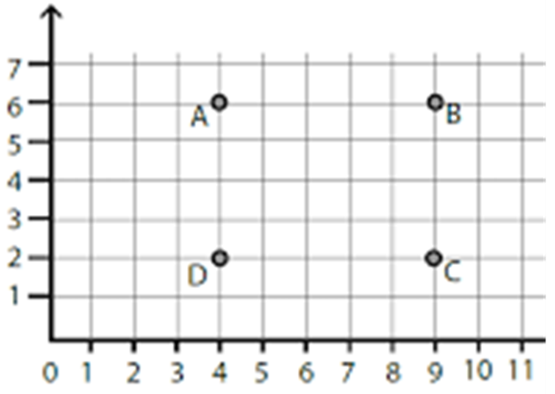

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;
tVec = 0:sampleTime:16;

initPose = [4;2;90];
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### **Carga del mapa y configuración del sensor LiDAR**

Se carga un mapa binario llamado `exampleMap`, que representa el entorno de trabajo del robot, incluyendo obstáculos.

close all
load exampleMap

A continuación, se configura un sensor LiDAR virtual. Este sensor está ubicado en el centro del robot, cubre un rango angular completo de -π a π (es decir, 360°) y genera 250 lecturas por escaneo. El alcance máximo del sensor es de 2 metros, lo cual limita su capacidad de detección de obstáculos lejanos.

lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,250);
lidar.maxRange = 2;

### Visualización 2D

viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [initPose(1:2)'; 
             4 6;
             9 6;
             9 2;];

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 20;

### Vector Field Histogram (VFH)

Para evitar colisiones, se emplea el algoritmo VFH. Este analiza las lecturas del LiDAR y determina qué direcciones de avance están libres de obstáculos. Se establecen parámetros como los límites de distancia de detección, el número de sectores angulares en los que se divide el espacio circundante, los umbrales para generar histograma de obstáculos, el radio del robot, una distancia de seguridad alrededor de él y el radio mínimo de giro que puede ejecutar.

vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 900; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L/2;
vfh.MinTurningRadius = 0.1;

### Bucle de simulación principal

Se inicia el ciclo de simulación sincronizado con el tiempo real simulado.

r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### a) Lectura del entorno con LiDAR

Se obtiene la pose actual del robot y el escaneo LiDAR desde esa pose.

    curPose = pose(:,idx-1);
    ranges = lidar(curPose);

#### b) Seguimiento de trayectoria y evasión de obstáculos

Luego se calcula la referencia de velocidad utilizando el controlador de Pure Pursuit, determinando la dirección hacia el punto adelantado. Esta dirección deseada se ajusta mediante el algoritmo VFH, que considera los obstáculos cercanos. Si el algoritmo determina que la dirección deseada no es segura, se genera una nueva dirección alternativa y se ajusta la velocidad angular para redirigir al robot.

    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    

#### c) Cálculo de velocidades y actualización de la pose

Posteriormente, se calculan las velocidades lineales y angulares en el sistema del robot. Estas se convierten al sistema de coordenadas global y se utiliza un paso de integración discreto para actualizar la pose del robot.

    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 

#### d) Visualización del movimiento

Se actualiza la visualización del robot, los waypoints y las lecturas del LiDAR, sincronizando la simulación con `rateControl`.

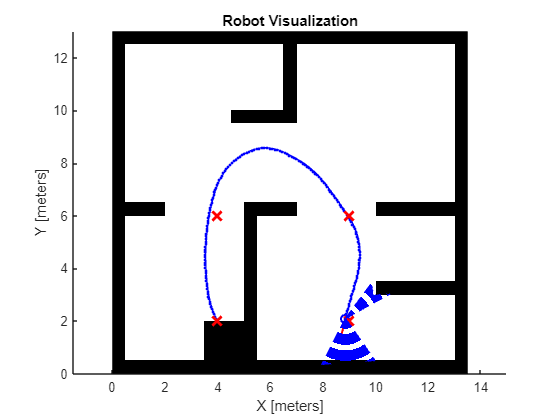

    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

## Segundo conjunto

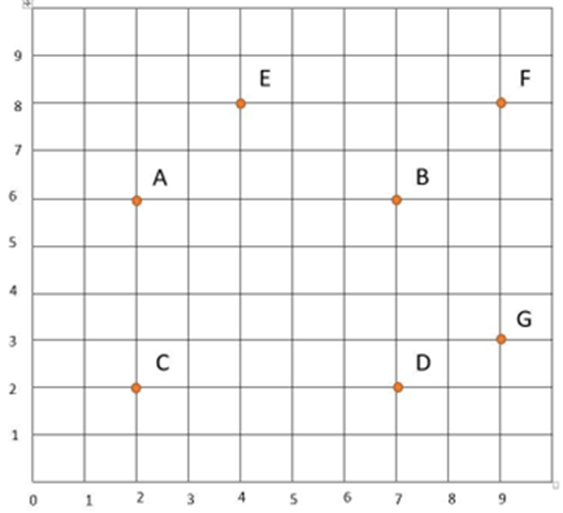

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;
tVec = 0:sampleTime:24;

initPose = [2;2;90];
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### **Carga del mapa y configuración del sensor LiDAR**

Se carga un mapa binario llamado `exampleMap`, que representa el entorno de trabajo del robot, incluyendo obstáculos.

close all
load exampleMap

A continuación, se configura un sensor LiDAR virtual. Este sensor está ubicado en el centro del robot, cubre un rango angular completo de -π a π (es decir, 360°) y genera 250 lecturas por escaneo. El alcance máximo del sensor es de 2 metros, lo cual limita su capacidad de detección de obstáculos lejanos.

lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,250);
lidar.maxRange = 2;

### Visualización 2D

viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [initPose(1:2)'; 
             2 6;
             4 8;
             9 8;
             7 6;
             7 2;
             9 3];

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 20;

### Vector Field Histogram (VFH)

Para evitar colisiones, se emplea el algoritmo VFH. Este analiza las lecturas del LiDAR y determina qué direcciones de avance están libres de obstáculos. Se establecen parámetros como los límites de distancia de detección, el número de sectores angulares en los que se divide el espacio circundante, los umbrales para generar histograma de obstáculos, el radio del robot, una distancia de seguridad alrededor de él y el radio mínimo de giro que puede ejecutar.

vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 900; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = 0.1;
vfh.SafetyDistance = 0.1;
vfh.MinTurningRadius = 0.1;

### Bucle de simulación principal

Se inicia el ciclo de simulación sincronizado con el tiempo real simulado.

r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### a) Lectura del entorno con LiDAR

Se obtiene la pose actual del robot y el escaneo LiDAR desde esa pose.

    curPose = pose(:,idx-1);
    ranges = lidar(curPose);

#### b) Seguimiento de trayectoria y evasión de obstáculos

Luego se calcula la referencia de velocidad utilizando el controlador de Pure Pursuit, determinando la dirección hacia el punto adelantado. Esta dirección deseada se ajusta mediante el algoritmo VFH, que considera los obstáculos cercanos. Si el algoritmo determina que la dirección deseada no es segura, se genera una nueva dirección alternativa y se ajusta la velocidad angular para redirigir al robot.

    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    

#### c) Cálculo de velocidades y actualización de la pose

Posteriormente, se calculan las velocidades lineales y angulares en el sistema del robot. Estas se convierten al sistema de coordenadas global y se utiliza un paso de integración discreto para actualizar la pose del robot.

    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 

#### d) Visualización del movimiento

Se actualiza la visualización del robot, los waypoints y las lecturas del LiDAR, sincronizando la simulación con `rateControl`.

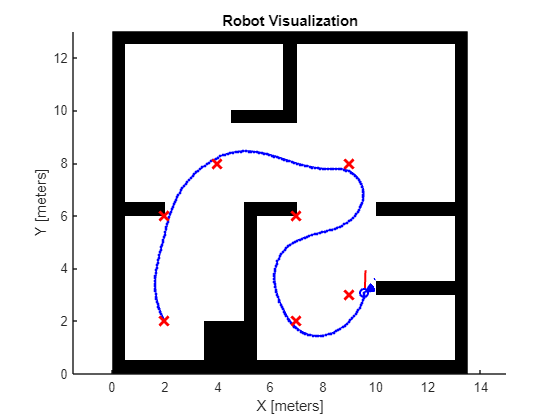

    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

## Tecer conjunto

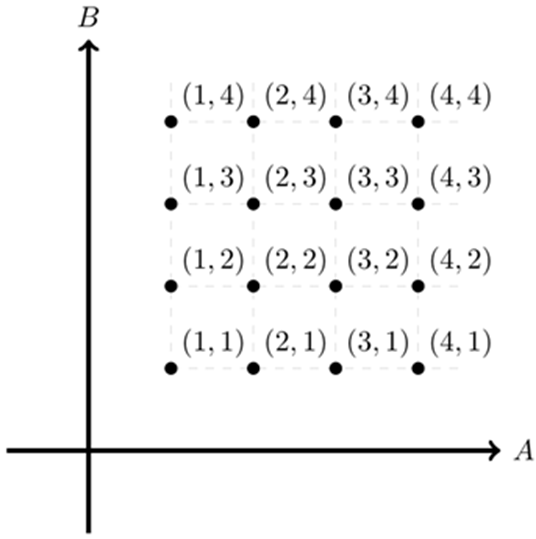

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;
tVec = 0:sampleTime:125;

initPose = [12;2;180];
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### **Carga del mapa y configuración del sensor LiDAR**

Se carga un mapa binario llamado `exampleMap`, que representa el entorno de trabajo del robot, incluyendo obstáculos.

close all
load exampleMap

A continuación, se configura un sensor LiDAR virtual. Este sensor está ubicado en el centro del robot, cubre un rango angular completo de -π a π (es decir, 360°) y genera 250 lecturas por escaneo. El alcance máximo del sensor es de 2 metros, lo cual limita su capacidad de detección de obstáculos lejanos.

lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,250);
lidar.maxRange = 2;

### Visualización 2D

viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [initPose(1:2)';
             9 2;
             6 2;
             12 5;
             9 5;
             6 5;
            12 8;
            12 11;
             9 11;
             9 8;
             6 8;
             3 2;
             3 5;
             3 8;
             3 11;
             6 11];

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 20;

### Vector Field Histogram (VFH)

Para evitar colisiones, se emplea el algoritmo VFH. Este analiza las lecturas del LiDAR y determina qué direcciones de avance están libres de obstáculos. Se establecen parámetros como los límites de distancia de detección, el número de sectores angulares en los que se divide el espacio circundante, los umbrales para generar histograma de obstáculos, el radio del robot, una distancia de seguridad alrededor de él y el radio mínimo de giro que puede ejecutar.

vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 900; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = 0.2;
vfh.SafetyDistance = 0.2;
vfh.MinTurningRadius = 0.01;

### Bucle de simulación principal

Se inicia el ciclo de simulación sincronizado con el tiempo real simulado.

r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### a) Lectura del entorno con LiDAR

Se obtiene la pose actual del robot y el escaneo LiDAR desde esa pose.

    curPose = pose(:,idx-1);
    ranges = lidar(curPose);

#### b) Seguimiento de trayectoria y evasión de obstáculos

Luego se calcula la referencia de velocidad utilizando el controlador de Pure Pursuit, determinando la dirección hacia el punto adelantado. Esta dirección deseada se ajusta mediante el algoritmo VFH, que considera los obstáculos cercanos. Si el algoritmo determina que la dirección deseada no es segura, se genera una nueva dirección alternativa y se ajusta la velocidad angular para redirigir al robot.

    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    

#### c) Cálculo de velocidades y actualización de la pose

Posteriormente, se calculan las velocidades lineales y angulares en el sistema del robot. Estas se convierten al sistema de coordenadas global y se utiliza un paso de integración discreto para actualizar la pose del robot.

    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 

#### d) Visualización del movimiento

Se actualiza la visualización del robot, los waypoints y las lecturas del LiDAR, sincronizando la simulación con `rateControl`.

    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

## complexMap

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;
tVec = 0:sampleTime:75;

initPose = [2;2;0];
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### **Carga del mapa y configuración del sensor LiDAR**

Se carga un mapa binario llamado `exampleMap`, que representa el entorno de trabajo del robot, incluyendo obstáculos.

close all
load complexMap

A continuación, se configura un sensor LiDAR virtual. Este sensor está ubicado en el centro del robot, cubre un rango angular completo de -π a π (es decir, 360°) y genera 250 lecturas por escaneo. El alcance máximo del sensor es de 2 metros, lo cual limita su capacidad de detección de obstáculos lejanos.

lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,250);
lidar.maxRange = 2;

### Visualización 2D

viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [initPose(1:2)';
             8 2;
             12 4
             8 8;
             2 8;
             4 12;
             12 12];

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 20;

### Vector Field Histogram (VFH)

Para evitar colisiones, se emplea el algoritmo VFH. Este analiza las lecturas del LiDAR y determina qué direcciones de avance están libres de obstáculos. Se establecen parámetros como los límites de distancia de detección, el número de sectores angulares en los que se divide el espacio circundante, los umbrales para generar histograma de obstáculos, el radio del robot, una distancia de seguridad alrededor de él y el radio mínimo de giro que puede ejecutar.

vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 900; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = 0.1;
vfh.MinTurningRadius = 0.1;

### Bucle de simulación principal

Se inicia el ciclo de simulación sincronizado con el tiempo real simulado.

r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### a) Lectura del entorno con LiDAR

Se obtiene la pose actual del robot y el escaneo LiDAR desde esa pose.

    curPose = pose(:,idx-1);
    ranges = lidar(curPose);

#### b) Seguimiento de trayectoria y evasión de obstáculos

Luego se calcula la referencia de velocidad utilizando el controlador de Pure Pursuit, determinando la dirección hacia el punto adelantado. Esta dirección deseada se ajusta mediante el algoritmo VFH, que considera los obstáculos cercanos. Si el algoritmo determina que la dirección deseada no es segura, se genera una nueva dirección alternativa y se ajusta la velocidad angular para redirigir al robot.

    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 5*steerDir;
    end
    

#### c) Cálculo de velocidades y actualización de la pose

Posteriormente, se calculan las velocidades lineales y angulares en el sistema del robot. Estas se convierten al sistema de coordenadas global y se utiliza un paso de integración discreto para actualizar la pose del robot.

    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 

#### d) Visualización del movimiento

Se actualiza la visualización del robot, los waypoints y las lecturas del LiDAR, sincronizando la simulación con `rateControl`.

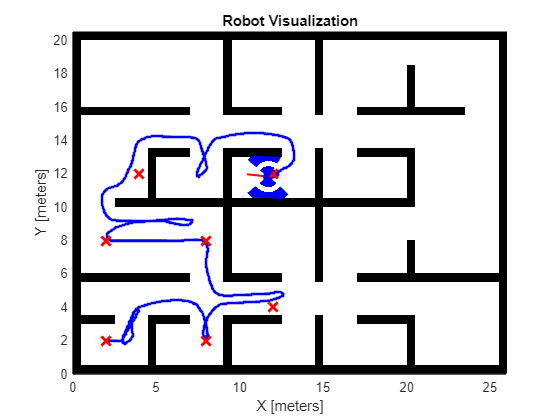

    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end